clear; close all;  clc;

This is based on Mike X Cohen video: [Morlet wavelets in time and in frequency - YouTube](https://www.youtube.com/watch?v=7ahrcB5HL0k&list=PLn0OLiymPak2BYu--bR0ADNBJsC4kuRWs)

# where do morelts come from?

syms t f s real

sine = exp(1i*2*pi*f*t);
gaus = exp(-0.5*(t/s)^2);
cmw = sine*gaus;

We can plot the real valued morlet wavelet by taking a sine wave and multiplying it by a gaussian

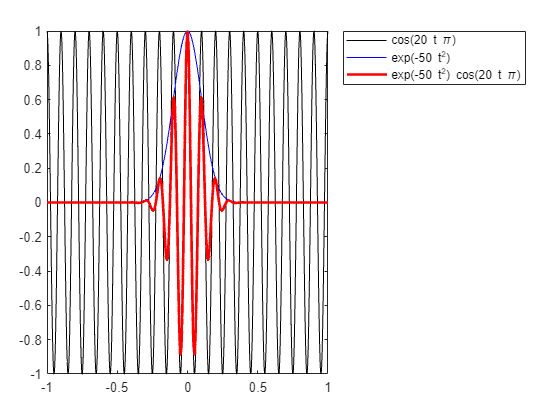

sine_plot = real(subs(sine,"f",10));
gaus_plot = subs(gaus,"s",0.1);
cmw_plot = sine_plot*gaus_plot;

figure;
xlimits = [-1 1];
fplot(sine_plot,xlimits,'k',LineWidth=0.5)
hold on;
fplot(gaus_plot,xlimits,'b',LineWidth=0.5)
fplot(cmw_plot,xlimits,"r",LineWidth=2)

legend(Location="bestoutside")

# The frequency domain of a morlet

The morlet can undergo a fourier transform to see that it's representation in the ferquency domain is a gaussian!

The gaussian will be centered at the sinusoudal frequency

CMW_hat = subs(fourier(cmw_plot),"w",2*pi*f)

$$CMW\_hat = \frac{\sqrt{50}\,\sqrt{\pi }\,{\mathrm{e}}^{-\frac{{\left(20\,\pi -2\,\pi \,f\right)}^{2}}{200}}}{100}+\frac{\sqrt{50}\,\sqrt{\pi }\,{\mathrm{e}}^{-\frac{{\left(20\,\pi +2\,\pi \,f\right)}^{2}}{200}}}{100}$$

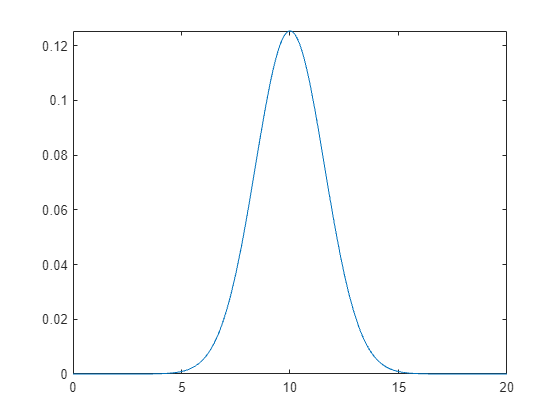


figure;
fplot(CMW_hat,[0 20])